# **Homework 1 - Calcolo Numerico Francesco Calcopietro Matr. 0124002090**

Data la traccia dell'Homework riportata nel file 'HW1_21.mlx', si vogliono eseguire i suoi punti spiegandone i vari risultati. 

#### **1. D**efinite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete `funrif`;

Il numero di lettere di 'Francesco' è 9, mentre il numero di lettere del cognome 'Calcopietro' è 11. Avendo questi numeri si costruisce la funzione *funrif* richiesta. Si fa uso del comando **exp **per il numero di Nepero e l'operatore **. **per definire le varie operazioni richieste componente per componente.

funrif= @(x) exp(-x).*((sin(((9*x)/2)-pi/2)).^2)+(11./(1+3*x.^2)).*sin(2.*x)-5;

#### **2. V**isualizzate il grafico della funzione di riferimento in $[a,b]$, specificando espicitamente quale intervallo avete scelto e indicando sul grafico (comando `text`) gli estremi dell'intervallo scelto, i 3 zeri, il primo valore minimo e l'ascissa del primo minimo (detta *punto di minimo 1*), il secondo valore minimo e l'ascissa del secondo minimo (detta *punto di minimo 2*), il valore massimo e l'ascissa del massimo (detta *punto di massimo*);

Di seguito si visualizza l'andamento della funzione in un grafico generico nell'intervallo [-5,5] per l'asse x, facendo uso del comando **fplot **e **grid**.

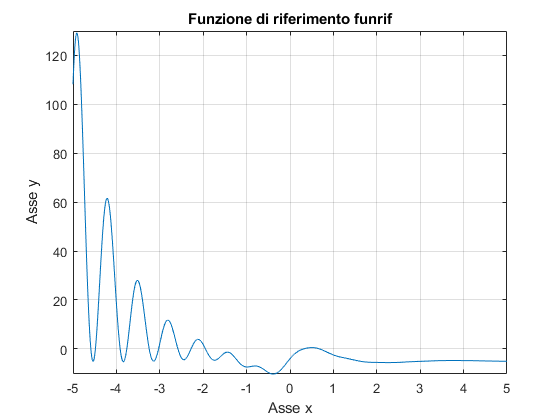

griglia =   -5.000000000000000  -4.898989898989899  -4.797979797979798  -4.696969696969697  -4.595959595959596  -4.494949494949495  -4.393939393939394  -4.292929292929292  -4.191919191919192  -4.090909090909091  -3.989898989898990  -3.888888888888889  -3.787878787878788  -3.686868686868687  -3.585858585858586  -3.484848484848485  -3.383838383838384  -3.282828282828283  -3.181818181818182  -3.080808080808080  -2.979797979797980  -2.878787878787879  -2.777777777777778  -2.676767676767677  -2.575757575757576  -2.474747474747475  -2.373737373737374  -2.272727272727272  -2.171717171717172  -2.070707070707071  -1.969696969696970  -1.868686868686869  -1.767676767676768  -1.666666666666667  -1.565656565656566  -1.464646464646465  -1.363636363636364  -1.262626262626263  -1.161616161616162  -1.060606060606061  -0.959595959595960  -0.858585858585859  -0.757575757575758  -0.656565656565657  -0.555555555555556  -0.454545454545455  -0.353535353535354  -0.252525252525253  -0.151515151515152  -0.05050

maxf =      1.288138907014333e+02


puntmax =      2


fplot(funrif,[-5 5])
title("Funzione di riferimento funrif")
xlabel("Asse x")
ylabel("Asse y")
grid on

Fatto ciò, si visualizza nuovamente il grafico di *funrif *ma questa volta andando a limitare i valori dell'intervallo di visualizzazione, in modo tale da poter avere precisamente: 3 zeri, 2 minimi e 1 massimo. L'intervallo scelto è $[-2.65,-1.65]$ per l'asse x e $[-6,5]$ per l'asse y. Per limitare l'intervallo sull'asse y si utilizza il comando **ylim. **Inoltre, attraverso il comando **text**, si definiscono i 9 valori di interesse.

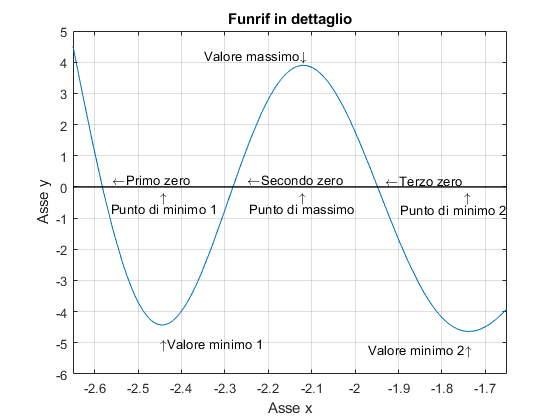

fplot(funrif,[-2.65 -1.65])
hold on
ylim([-6 5])
title("Funrif in dettaglio")
xlabel("Asse x")
ylabel("Asse y")
text(-2.56, 0.25, '\leftarrowPrimo zero', 'HorizontalAlignment', 'left')
text(-2.25, 0.25, '\leftarrowSecondo zero', 'HorizontalAlignment', 'left')
text(-1.93, 0.22, '\leftarrowTerzo zero', 'HorizontalAlignment', 'left')
text(-2.11, 4.22, 'Valore massimo\downarrow','HorizontalAlignment','right')
text(-2.12, -0.30, '\uparrow','HorizontalAlignment','center')
text(-2.44, -0.30, '\uparrow','HorizontalAlignment','center')
text(-1.74, -0.30, '\uparrow','HorizontalAlignment','center')
text(-1.65, -0.72, 'Punto di minimo 2','HorizontalAlignment','right');
text(-2, -0.68, 'Punto di massimo','HorizontalAlignment','right');
text(-2.44, -0.68, 'Punto di minimo 1','HorizontalAlignment','center');
text(-2.21, -5, '\uparrowValore minimo 1','HorizontalAlignment','right')
text(-1.73, -5.2, 'Valore minimo 2\uparrow','HorizontalAlignment','right')
plot([-2.65 -1.65] ,[0 0],'k','linewidth',1)
grid on
hold off

#### **3. U**sate la function Matlab `fzero` per determinare i 3 zeri della vostra funzione di riferimento in $[a,b]$, e considerate i valori calcolati da `fzero` come le soluzioni esatte

Come espresso dalla traccia, si utilizza la funzione del Matlab *fzero* per poter calcolare i 3 zeri della funzione *funrif*. Tale funzione prende in input la funzione di riferimento e l'approssimazione iniziale. Quest'ultima può essere o uno scalare o un intervallo di approssimazione. Si sceglie la prima alternativa. Come richiesto, ogni risultato sarà definito in formato long, in modo tale da poter visualizzare tutte le 16 cifre.

z1=fzero(funrif,-2.5);
format long
z1

z1 =   -2.582357628508949


z1 indica lo zero più a sinistra.

z2=fzero(funrif,-2.3)

z2 =   -2.281439019526597


z2

z2 =   -2.281439019526597


z2 indica lo zero centrale. 

z3=fzero(funrif,-2);
z3

z3 =   -1.948157899108695


z3 indica lo zero più a destra. 

Il grafico seguente definisce i 3 zeri della funzione appena calcolati.

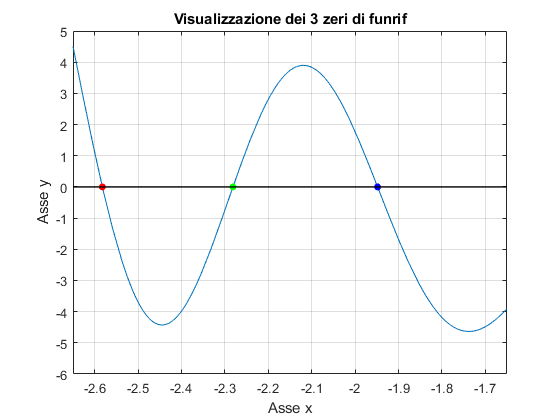

fplot(funrif,[-2.65 -1.65])
ylim([-6 5])
hold on
title("Visualizzazione dei 3 zeri di funrif")
xlabel("Asse x")
ylabel("Asse y")
plot(z1,0,'.r','Markersize',18)
plot(z2,0,'.g','Markersize',18)
plot(z3,0,'.b','Markersize',18)
grid on
plot([-2.65 -1.65] ,[0 0],'k','linewidth',1)
hold off

#### 4. Determinate un'approssimazione dei 3 zeri, usando il metodo di bisezione (nostra function `bisezione`) per lo zero più piccolo, il metodo delle Secanti (nostra function `Secanti`) per lo zero centrale e il metodo di Newton (nostra function `Newton`) per lo zero più grande (consiglio: usare `funtool` per determinare l'espressione della derivata della funzione di riferimento), con un valore di `delta_ass` che garantisca, in tutti e 3 i casi, che la parte intera e le prime 7 cifre frazionarie siano corrette

Come richiesto della traccia, si richiama la funzione *bisezione* per poter calcolare un'approssimazione dello zero più a sinistra attraverso il metodo della bisezione. Tale funzione prende in input: la funzione di riferimento, l'intervallo $[a,b]$, tale che funrif(a) * funrif(b) <= 0, e l'accurattezza richiesta delta_ass definita in modo tale da poter garantire parte intera e le prime 7 cifre frazionarie corrette rispetto allo zero calcolato con *fzero.*

delta_ass=1.e-7;
zB1=bisezione(funrif,-2.6,-2.4,delta_ass);
zB1

zB1 =   -2.582357645034790


z1

z1 =   -2.582357628508949


zB1 è l'approssimazione dello zero più a sinistra della funzione *funrif. *Come si può notare, quest'ultima è corretta secondo quanto richiesto dalla traccia cioè garantisce parte intera e le prime 7 cifre decimali uguali rispetto al primo zero calcolato con *fzero,* cioè z1.

Si richiama la funzione *secanti* per poter calcolare un'approssimazione dello zero centrale attraverso il metodo delle secanti.Tale funzione prende in input: la funzione di riferimento, 2 approssimazioni iniziali della soluzione, l'accuratezza richiesta delta_ass, la quale anche qui deve garantire che siano accurate: la parte intera e le prime 7 cifre decimali rispetto allo zero corrispondente, calcolato con *fzero.* Infine *secanti* prende in input anche kmax, un intero opzionale che sta ad indicare il massimo numero di iterazioni consentite per rafforzare il criterio di arresto nel caso in cui il metodo non dovesse convergere. 

kmax=30;
delta_ass=1.e-7;
zS2=Secanti(funrif,-2.21,-2.2,delta_ass,kmax);
zS2

zS2 =   -2.281439029697708


z2

z2 =   -2.281439019526597


zS2 è l'approssimazione dello zero centrale della funzione *funrif.* Anche qui, come si può notare sono rispettate le richieste della traccia sull'accuratezza richiesta. 

Si richiama la funzione *newton* per poter calcolare un'approssimazione dello zero più a destra attraverso il metodo di Newton. Tale funzione prende in input: la funzione di riferimento, la derivata di quest'ultima, calcolata con **Funtool**, un'approssimazione iniziale, l'accuratezza richiesta delta_ass, la quale deve anche qui rispettare le stesse richieste per i metodi precedenti, e kmax, un intero opzionale che sta ad indicare il massimo numero di iterazioni consentite per rafforzare il criterio di arresto nel caso in cui il metodo non dovesse convergere.

delta_ass=1.e-7;
kmax=30;
derivata= @(x) (22*cos(2*x))./(3*x.^2+1)-sin((9*x)/2-pi/2).^2.*exp(-x)-(66*x.*sin(2*x))./(3*x.^2+1).^2+9*cos((9*x)./2-pi/2).*sin((9*x)./2-pi/2).*exp(-x);
zN3=Newton(funrif,derivata,-2.05,delta_ass,kmax);
zN3

zN3 =   -1.948157899108640


z3

z3 =   -1.948157899108695


zN3 è l'approssimazione richiesta per il terzo zero, quello più a destra della funzione *funrif.* Si può notare anche qui come l'accuratezza richiesta abbia rispettato le richieste della traccia. 

Il grafico seguente visualizza lo zero appena calcolato e contemporaneamente l'andamento della derivata della funzione di riferimento.

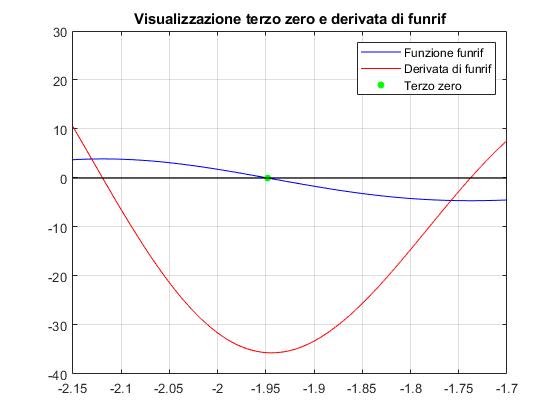

fplot(funrif,[-2.15 -1.7],'b')
title("Visualizzazione terzo zero e derivata di funrif")
hold on
fplot(derivata,[-2.15 -1.7],'r')
ylim([-40 30])
plot(z3,0,'.g','Markersize',18)
plot([-2.15 -1.7] ,[0 0],'k','linewidth',1)
legend("Funzione funrif","Derivata di funrif","Terzo zero")
grid on
hold off

#### 5. Considerate sia l'errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione delle Secanti e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta e verificate che siano minori dell'accuratezza richiesta (`delta_ass`), commentando il loro valore; calcolate anche il residuo per ognuna delle tre approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; guardando il grafico della funzione di riferimento dire se, per ognuno dei tre zeri, il problema appare bene o mal condizionato e poi calcolare l'indice di condizionamento per ognuno dei tre zeri

err_ass_Bis=abs(z1-zB1);
err_ass_Sec=abs(z2-zS2);
err_ass_New=abs(z3-zN3);
residuo_zB1=abs(funrif(zB1));
residuo_zS2=abs(funrif(zS2));
residuo_zN3=abs(funrif(zN3));
indice_cond_z1=abs(derivata(z1))^(-1);
indice_cond_z2=abs(derivata(z2))^(-1);
indice_cond_z3=abs(derivata(z3))^(-1);
err_ass_Bis

err_ass_Bis =      1.652584069589125e-08


residuo_zB1

residuo_zB1 =      9.951140809150161e-07


indice_cond_z1

indice_cond_z1 =    0.016606981889635


err_ass_Sec

err_ass_Sec =      1.017111106449420e-08


residuo_zS2

residuo_zS2 =      4.045683681397350e-07


indice_cond_z2

indice_cond_z2 =    0.025140648750660


err_ass_New

err_ass_New =      5.440092820663267e-14


residuo_zN3

residuo_zN3 =      1.930899884428072e-12


indice_cond_z3

indice_cond_z3 =    0.028039511283263


Applicando le formule per ricavare i vari errori, si può notare come tutti e 3 gli errori assoluti siano più piccoli dell'accuratezza richiesta. Rispettivamente si avranno 2 errori dell'ordine di $10^-8$ e un errore dell'ordine di $10^-14$ rispetto all'ordine di $10^-7$ dell'accuratezza richiesta delta_ass.

Per quanto riguarda i residui, si hanno delle quantità, in tutti e 3 i casi, molto simili, in termini di grandezze, ai rispettivi errori assoluti. Differenziano solo di 1 o 2 ordini. Da questo si può capire il fatto che, in tutti e tre i casi, si hanno problemi ben condizionati. Questo lo si può capire anche visualizzando i valori delle 3 variabili usufruite proprio per calcolare i 3 indici di condizionamento. Sono tutti valori molto vicini allo zero. Infine quest'ultimo aspetto lo si può notare, ancora una volta, visualizzando direttamente l'andamento della funzione vicino agli zeri nel grafico alla fine di questa sezione. Essa, in tutti e 3 i casi, non ha un andamento "piatto" o costante.

fplot(funrif,[-2.65 -1.65])
ylim([-6 5])
hold on
title("Visualizzazione dei 3 zeri di funrif")
xlabel("Asse x")
ylabel("Asse y")
plot(z1,0,'.r','Markersize',18)
plot(z2,0,'.g','Markersize',18)
plot(z3,0,'.b','Markersize',18)
plot([-2.65 -1.65] ,[0 0],'k','linewidth',1)
grid on
hold off

#### 6. Usate la function Matlab `fminbnd` per determinare i due punti di minimo e il punto di massimo della vostra funzione di riferimento in $[a,b]$, con tre chiamate del tipo: `fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`, e considerate i valori calcolati da `fminbnd` come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e del punto di massimo)

La funzione fminbnd prenderà in input: la funzione di riferimento, gli estremi dell'intervallo in cui la funzione contiene il punto di interesse e optimset.

xmin1=fminbnd(funrif,-2.55,-2.4,optimset('TolX',1e-10));
xmin2=fminbnd(funrif,-1.9,-1.7,optimset('TolX',1e-10));
xmax=fminbnd(@(x) -funrif(x),-2.15,-2.10,optimset('TolX',1e-10));
xmin1

xmin1 =   -2.444848092822299


xmin2

xmin2 =   -1.737940813022083


xmax

xmax =   -2.119280606901936


Per verificare la validità dei valori appena ottenuti si definsice il seguente grafico:

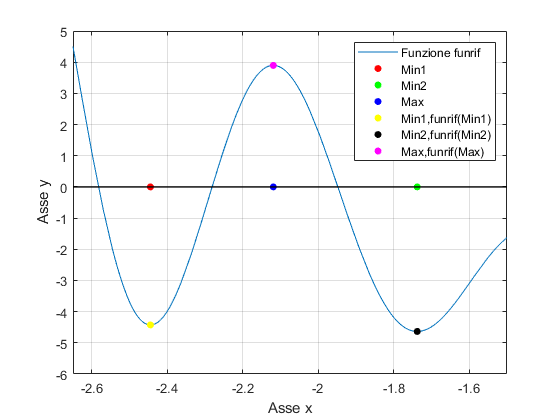

fplot(funrif,[-2.65 -1.5])
hold on
ylim([-6 5])
xlabel("Asse x")
ylabel("Asse y")
plot(xmin1,0,'.r','Markersize',18)
plot(xmin2,0,'.g','Markersize',18)
plot(xmax,0,'.b','Markersize',18)
plot(xmin1,funrif(xmin1),'.y','Markersize',18)
plot(xmin2,funrif(xmin2),'.black','Markersize',18)
plot(xmax,funrif(xmax),'.m','Markersize',18)
plot([-2.65 -1.5] ,[0 0],'k','linewidth',1)
legend("Funzione funrif","Min1","Min2","Max","Min1,funrif(Min1)","Min2,funrif(Min2)","Max,funrif(Max)")
hold off
grid on 

Per questioni di spazio mancante dovuto dalla presenza della legenda, si cambia leggermente l'intervallo di visualizzazione rispetto alle sezioni precedenti  in $[-2.65,-1.5]$. In questo grafico si può vedere come i valori calcolati siano accurati. 

#### 7. Verificate che i due punti di minimo e il punto di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare `funtool` per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione sia il grafico della sua derivata (può essere utile usare anche la scalatura della finestra grafica data dal comando `axis([xmin xmax ymin ymax])` ), e usando la `fzero` per calcolare gli zeri della derivata; commentate i risultati ottenuti

Possiamo verificare la richiesta definita dalla traccia in due modi: attraverso un grafico andando a definire i 3 punti che hanno come valore di ascissa rispettivamente i 3 punti (minimi e massimo) e come ordinata 0. Si vede se tali punti corrispondono proprio ai 3 zeri della derivata.

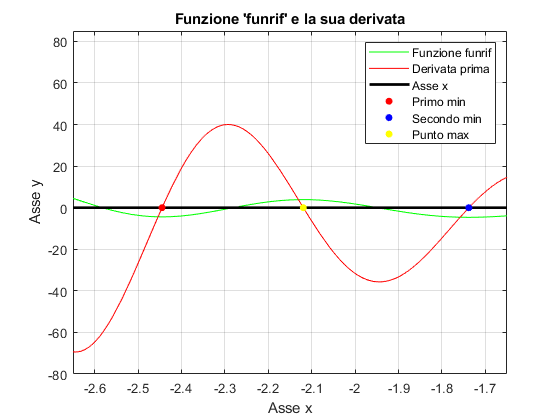

fplot(funrif,[-2.65 -1.65],'g')
hold on
fplot(derivata,[-3 -1.5],'r')
xlim([-2.65 -1.65])
ylim([-80 85])
title("Funzione 'funrif' e la sua derivata")
xlabel("Asse x")
ylabel("Asse y")
plot([-80 85],[0 0],'k','linewidth',2)
plot(xmin1,0,'.r','Markersize',18)
plot(xmin2,0,'.b','Markersize',18)
plot(xmax,0,'.y','Markersize',18)
legend('Funzione funrif','Derivata prima','Asse x','Primo min','Secondo min','Punto max')
grid on
hold off

Come si può notare dal grafico i 2 punti di minimo e il punto di massimo di *funrif *sono proprio i 3 zeri della derivata.

Possiamo avere una conferma di ciò andando a richiamare la *fzero* sulla derivata passando come approssimazioni inziali 3 valori vicini agli zeri.

Zd1=fzero(derivata,-2.5);
Zd2=fzero(derivata,-2.2);
Zd3=fzero(derivata,-1.8);
Zd1

Zd1 =   -2.444848092569620


xmin1

xmin1 =   -2.444848092822299


Zd2

Zd2 =   -2.119280606542650


xmax

xmax =   -2.119280606901936


Zd3

Zd3 =   -1.737940812443518


xmin2

xmin2 =   -1.737940813022083


Come si può notare i tre zeri della derivata corrispondono proprio ai 2 punti di minimo e al punto di massimo di *funrif.*

#### 8. Determinate un'approssimazione dei due punti di minimo e del punto di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function `fminfibo`) per i due minimi , e il metodo di Golden search (nostra function `fmingolden`) per il massimo, con un valore di `delta_ass` che garantisca che la parte intera e le prime 4 cifre frazionarie siano corrette

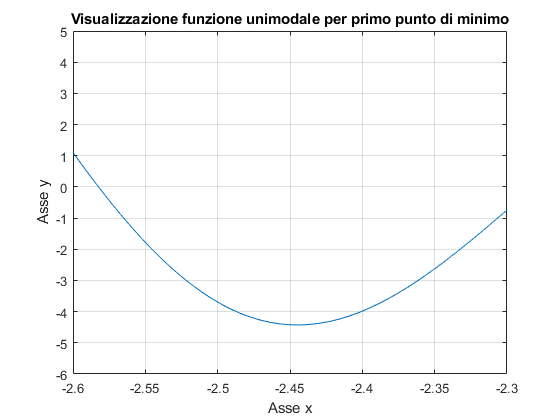

fplot(funrif,[-2.6 -2.3])
ylim([-6 5])
hold on
title("Visualizzazione funzione unimodale per primo punto di minimo")
xlabel("Asse x")
ylabel("Asse y")
grid on
hold off

Siccome si utilizza la funzione fminfibo si deve considerare un intervallo nella quale la funzione sia unimodale. Per il primo punto di minimo si considera l'intervallo $[-2.6,-2.3]$ nella quale la funzione rispetta tale caratteristica. Questo è dimostrato dal grafico sopra definito. Viene definita un'accuratezza tale che si possa garantire la correttezza delle prime 4 cifre frazionali corrette. 

min1fibo=fminfibo(funrif,-2.6,-2.3,1e-4);
min2fibo=fminfibo(funrif,-1.80009,-1.6,1.e-4);
maxgolden=fmingolden(@(x) -funrif(x),-2.4,-1.8,1e-4);
min1fibo

min1fibo =   -2.444832826747721


xmin1

xmin1 =   -2.444848092822299


Come si può notare i due valori hanno le prime 4 cifre frazionarie uguali.

Lo stesso grafico viene fatto per visualizzare una funzione unimodale per calcolare il secondo punto di minimo. L'intervallo su cui ci si focalizza è $[-1.80009,-1.6]$. Si nota che l'estremo sinistro di tale intervallo non è del tutto "ristretto" come quello destro per il semplice fatto che la fminfibo non garantiva le prime 4 cifre decimali corrette bensì solo 3.

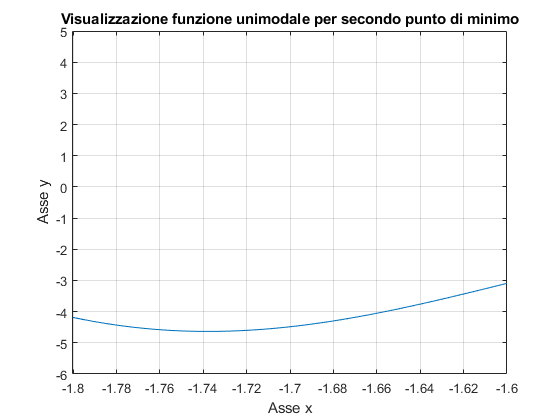

fplot(funrif,[-1.80009 -1.6])
ylim([-6 5])
hold on
title("Visualizzazione funzione unimodale per secondo punto di minimo")
xlabel("Asse x")
ylabel("Asse y")
grid on
hold off


min2fibo

min2fibo =   -1.737930893442623


xmin2

xmin2 =   -1.737940813022083


Come si può notare i due valori hanno le prima 4 cifre frazionarie uguali.

Come fatto per i valori precedenti, viene mostrato anche qui un grafico per visualizzare l'intervallo scelto, $[-2.4,-1.8]$ nella quale la funzione è unimodale, per definire un'approssimazione del punto di massimo. Viene scelto, ancora una volta un delta_ass che assicuri 4 cifre decimali corrette oltre alla parte intera.

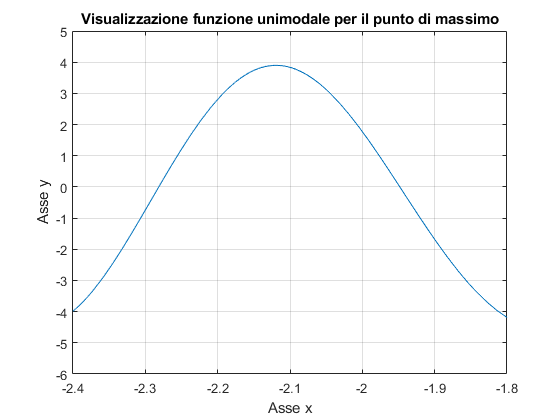

fplot(funrif,[-2.4 -1.8])
ylim([-6 5])
hold on
title("Visualizzazione funzione unimodale per il punto di massimo")
xlabel("Asse x")
ylabel("Asse y")
grid on
hold off

maxgolden

maxgolden =   -2.119285968599421


xmax

xmax =   -2.119280606901936


Come si può notare i due valori hanno le prime 4 cifre frazionarie uguali.

#### 9. Considerate l'errore assoluto tra l'approssimazione di Golden search e la corrispondente soluzione esatta e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e tre i casi minori dell'accuratezza richiesta (`delta_ass`), commentando i risultati

err_min1_F=abs(min1fibo-xmin1);
err_min2_F=abs(min2fibo-xmin2);
err_max_G=abs(maxgolden-xmax);
err_min1_F

err_min1_F =      1.526607457780216e-05


err_min2_F

err_min2_F =      9.919579460060390e-06


err_max_G

err_max_G =      5.361697484662642e-06


In tutti e 3 i casi si hanno risultati più piccoli dell'accuratezza richiesta. Infatti delta_ass è dell'ordine di $10^-4$ mentre qui si hanno valori dell'ordine di $10^-5$ e $10^-6$.